## Simulation of evolution of populations of hBN

### Using the 3-level model

clear 
clc
close all

K0 = zeros(3,3);
beta = 0.3;
k_21 = 440.7;
k_12 = beta * k_21;
k_23 = 14.73;
k_31 = 44.95;
K0(1,2) = k_12;
K0(2,1) = k_21;
K0(2,3) = k_23;
K0(3,1) = k_31;

K0_ON = K0;     %K matrix when laser is on

ode1_ON = @(t, y) K0_ON(1,1)*y(1) - K0_ON(1,1)*y(1)...
                 + K0_ON(2,1)*y(2) - K0_ON(1,2)*y(1)...
                 + K0_ON(3,1)*y(3) - K0_ON(1,3)*y(1);
ode2_ON = @(t, y) K0_ON(1,2)*y(1) - K0_ON(2,1)*y(2)...
                 + K0_ON(2,2)*y(2) - K0_ON(2,2)*y(2)...
                 + K0_ON(3,2)*y(3) - K0_ON(2,3)*y(2);
ode3_ON = @(t, y) K0_ON(1,3)*y(1) - K0_ON(3,1)*y(3)...
                 + K0_ON(2,3)*y(2) - K0_ON(3,2)*y(3)...
                 + K0_ON(3,3)*y(3) - K0_ON(3,3)*y(3);

odes_ON = @(t, n) [ode1_ON(t, n); ode2_ON(t, n); ode3_ON(t, n)];

init_ON = [1; 0; 0];
[t, n_res_ON] = ode45(odes_ON, [0 : 1e-4 : 1e-1], init_ON);

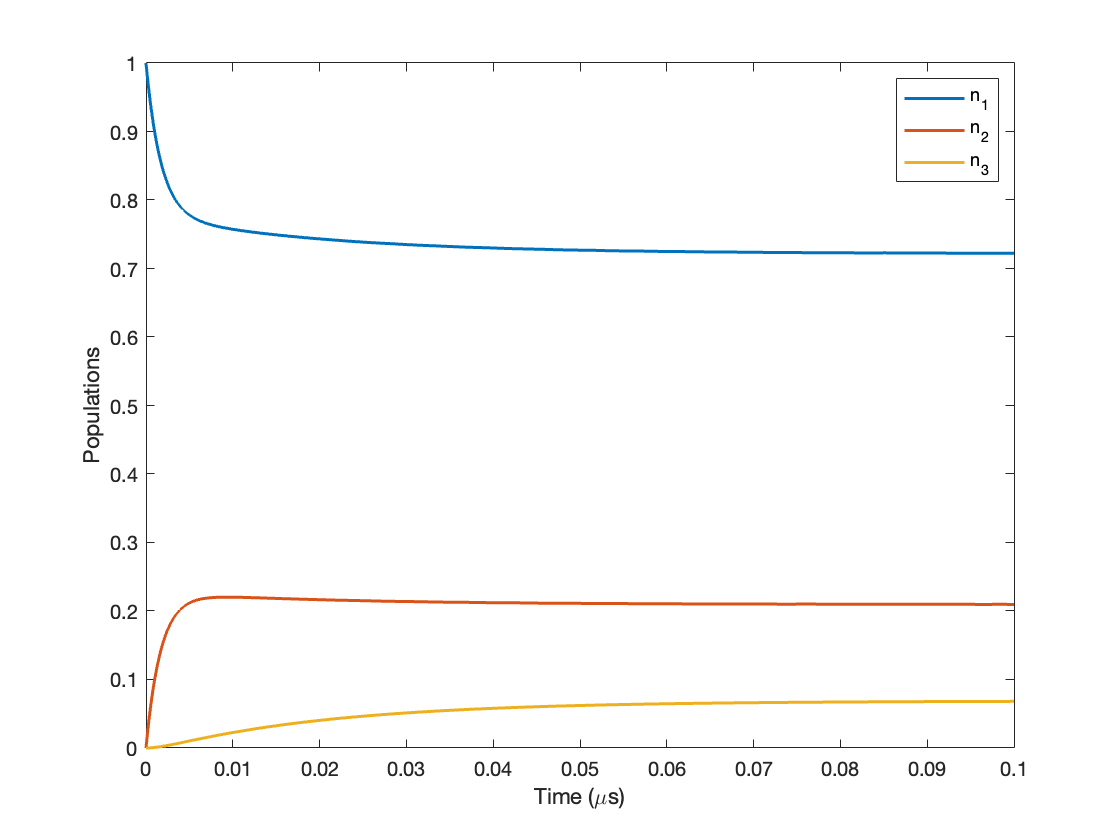

plot(t, n_res_ON, 'LineWidth',1.5);
xlabel('Time (\mus)');
ylabel('Populations');
legend('n_1', 'n_2', 'n_3');

n_res_2 = n_res_ON(:, 2);
tau_arr = 0 : 1e-4 : 3e-2;
length = size(tau_arr);
g2_arr = zeros(length);
for i = 1 : length(2)
    g2_arr(i) = n_res_2(i) / n_res_2(end);
end

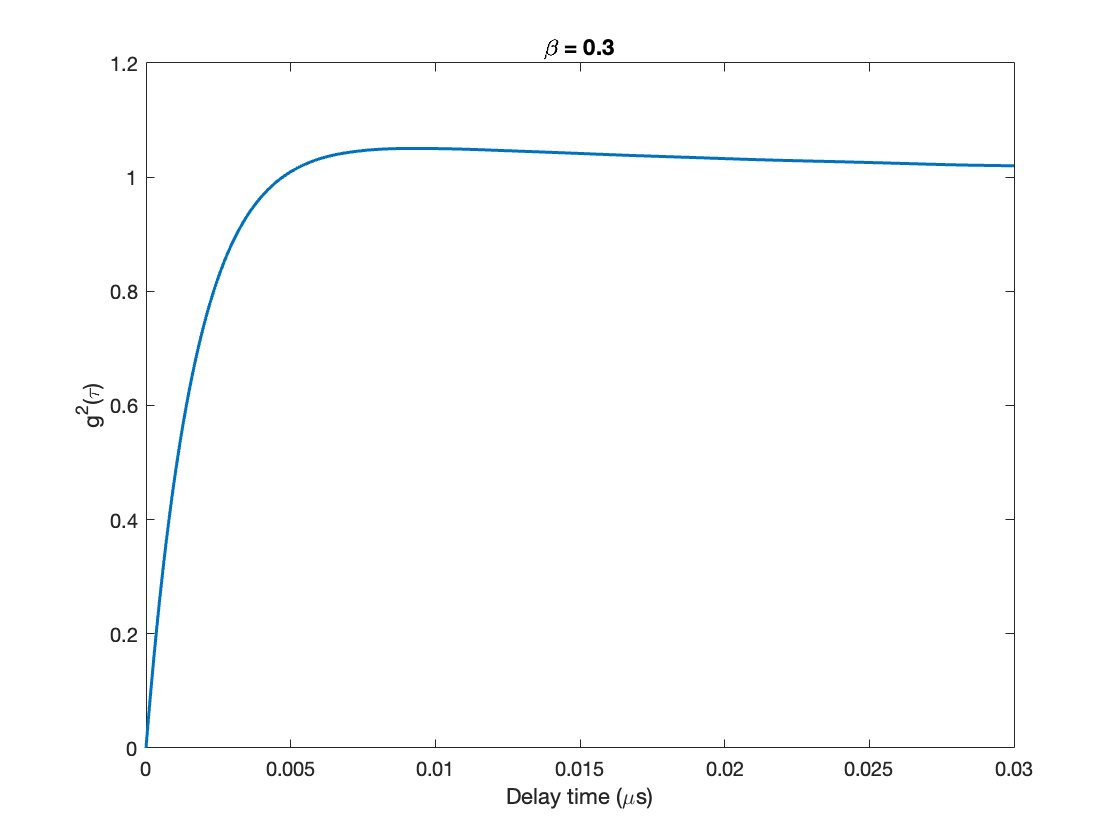

plot(tau_arr, g2_arr, 'LineWidth',1.5);
xlabel('Delay time (\mus)');
ylabel('g^2(\tau)');
title('\beta = 0.3');

% init_OFF = get_init(n_res_ON);
% [t, n_res_OFF] = ode45(odes_OFF, [0 : 1e-4 : 5e-2], init_OFF);

% plot(t, n_res_OFF, 'LineWidth',1.5);
% xlabel('Time (\mus)');
% ylabel('Populations');
% legend('n_1', 'n_2', 'n_3');

% n_res_OFF(1, :) = [];
% n_res = [n_res_ON; n_res_OFF];
% t = 0 : 1e-4 : 1e-1;
% plot(t, n_res, 'LineWidth',1.5);
% xlabel('Time (\mus)');
% ylabel('Populations');
% legend('n_1', 'n_2', 'n_3');

### Set up of the autocorrelation experiment

%{
    Name: counter
    Description: Records the delay time between consecutive photon hits of detectors D1 and D2
                 Called after each photon is emitted
    Input: 
    Output: delay time tau
%}
    

function init = get_init(arr)
    init = zeros(3,1);
    for i = 1:3
        init_temp = arr(:, i);
        init(i, 1) = init_temp(end);
    end
end